Getting Data

Wetted_AR = [1.874, 5.939, 2.992, 4.474, 5.145, 3.118]'

Wetted_AR =     1.8740
    5.9390
    2.9920
    4.4740
    5.1450
    3.1180


L_D_max = [6.103, 22.047, 9.198, 21.772, 18.024, 10.219]'

L_D_max =     6.1030
   22.0470
    9.1980
   21.7720
   18.0240
   10.2190


Getting Square root

sqrt_AR = sqrt(Wetted_AR)

sqrt_AR =     1.3689
    2.4370
    1.7297
    2.1152
    2.2683
    1.7658


Getting Regression throgh origin

slope = sqrt_AR\L_D_max

slope = 7.7722

avg_L_D = mean(L_D_max)

avg_L_D = 14.5605

sqrt_AR_wet = avg_L_D/slope

sqrt_AR_wet = 1.8734

Est_AR_wet = sqrt_AR_wet^2

Est_AR_wet = 3.5097

Plot

figure(1)
p1 = scatter(sqrt_AR,L_D_max,ColorVariable="black")

p1 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [1.3689 2.4370 1.7297 2.1152 2.2683 1.7658]
              YData: [6.1030 22.0470 9.1980 21.7720 18.0240 10.2190]
           SizeData: 36
              CData: [0 0.4470 0.7410]

  Show all properties


hold on
x_limit = [0,3]

x_limit =      0     3


p2 = plot(x_limit,slope*x_limit,'-',Color="green")

p2 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 3]
              YData: [0 23.3166]

  Show all properties


grid on 
hold on
p3 = yline(avg_L_D,'--',Label="Average $\left( \frac{L}{D} \right)_{max}$",Interpreter="latex",Color="red")

p3 =   ConstantLine (Average $\left( \frac{L}{D} \right)_{max}$) with properties:

    InterceptAxis: 'y'
            Value: 14.5605
            Color: [1 0 0]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: 'Average $\left( \frac{L}{D} \right)_{max}$'
      DisplayName: ''

  Show all properties


hold on
p4 = xline(sqrt_AR_wet,'--',"Estimated $\sqrt{AR_{wet}}$",Interpreter="latex",Color="blue")

p4 =   ConstantLine (Estimated $\sqrt{AR_{wet}}$) with properties:

    InterceptAxis: 'x'
            Value: 1.8734
            Color: [0 0 1]
        LineStyle: '--'
        LineWidth: 0.5000
            Label: 'Estimated $\sqrt{AR_{wet}}$'
      DisplayName: ''

  Show all properties


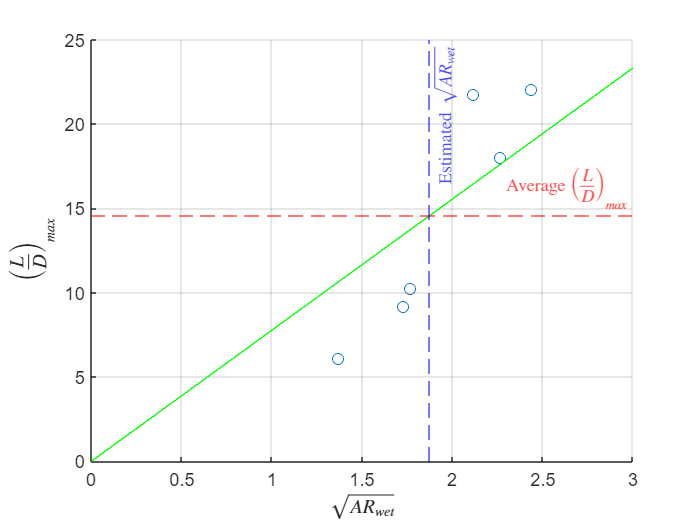

ylabel("$\left( \frac{L}{D} \right)_{max}$",Interpreter="latex")
xlabel("$\sqrt{AR_{wet}}$",Interpreter="latex")
xlim(x_limit)
hold off
saveas(gcf,"AR_wergraph.png")